The objective of the current script is to decompose resting-state OIS + LSCI imaging datasets of the mouse barrel cortex into functional component/structures. The hypothesis is that structures that could resemble barrels can be identified this way.

%Enter path to data for a single scan
folderPath = 'E:\Data Jeremie\Bilateral Stim and Resting State dataset\M4\M4_rs_10min';
%Open raw .bin files only if raw data files have not already been openned using OpenIOI_NewSyst.
data_are_openned = 1;
if ~data_are_openned
    Binning = 1;
    OpenIOI_NewSyst(folderPath,Binning,3,0);
end

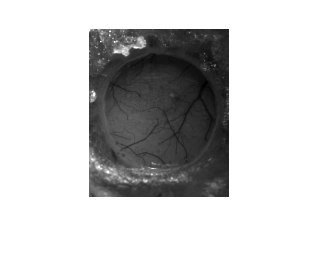

GreenFrames = FunctionalImagingMovie(folderPath,'green');
GreenFrames.correctMotion

mask = GreenFrames.createMask;
GreenFrames.applyMask(mask);

GreenFrames.zscore;